Compare

clear
% Set default figure size (in inches)
% set(groot, 'defaultFigureUnits', 'inches');
% set(groot, 'defaultFigurePosition', [1, 1, 6, 4]); % Width = 6 inches, Height = 4 inches
% 
% % Set default font settings for all text in plots
% set(groot, 'defaultAxesFontName', 'Times New Roman');
% set(groot, 'defaultAxesFontSize', 12); % Font size for axis labels and ticks
% set(groot, 'defaultTextFontSize', 12); % Font size for text in the plot
% set(groot, 'defaultAxesTitleFontSizeMultiplier', 1.2); % Slightly larger title
% set(groot, 'defaultLegendFontSize', 11); % Font size for legend text
% 
% % Set default line and marker settings
% set(groot, 'defaultLineLineWidth', 1.5); % Default line width
% set(groot, 'defaultLineMarkerSize', 8); % Default marker size
% 
% % Set default box and grid
% set(groot, 'defaultAxesBox', 'on'); % Enable box around plots by default
% set(groot, 'defaultAxesGridLineStyle', '-'); % Solid grid lines
% set(groot, 'defaultAxesXGrid', 'on'); % Enable grid for X axis
% set(groot, 'defaultAxesYGrid', 'on'); % Enable grid for Y axis

global airfoil cruise1 cruise2 C_cruise Wto Swet_SrefWing Swet_SrefBody l_d bdes bodyDiameter Srefdes Damping tolerance
bodyDiameter = 6.38;
Damping = 0.03;
tolerance = 1e-4;
cruise1 = AirCondition();
cruise1.M = 0.83;
cruise1.h = convlength(28000, 'ft','m');

cruise2 = AirCondition();
cruise2.V = convvel(400, 'kts', 'm/s');
cruise2.h = convlength(18000, 'ft','m');
cruise2 = cruise2.calcM();

C_cruise = 0.5 ./ 3600;

Swet_SrefWing = 2.2;
Swet_SrefBody = 5;
l_d = 10;

Srefdes = 548.7;
polarPath =  '../Airfoils/Airfoil polar data'; % Specify your directory path here
XYPath =  '../Airfoils/Airfoil XY data'; % Specify your directory path here

bdes = 65;
x0 = [11, 8, 2.75, 30*pi/180, 30*pi/180, 12, deg2rad(-3)];
%x0 = [cr, ck, ct, Lambdain50, Lambdaout50, yk, maxtwist in radians]
% Design variables 
lb = x0.*0.5;
%lb(7) = deg2rad(3);
ub = x0.*1.5;
%ub(7) = deg2rad(3);
wing0 = x2wing(x0);


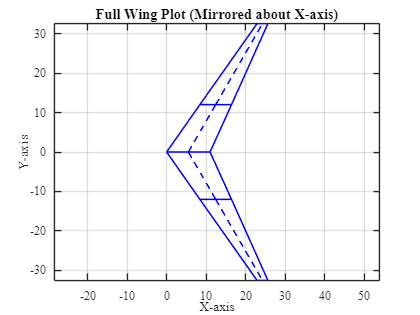

% Create an instance of WingGeometry
wing = WingGeometry();

% Assign properties
wing.cr = 11.0;                    % Root chord length in meters
wing.ck = 8.0;                     % Kink chord length in meters
wing.ct = 2.75;                    % Tip chord length in meters
wing.s = 65/2;                    % Semi-wingspan in meters
wing.yk = 12;                   % Spanwise location of the kink in meters
wing.Lambdain50 = deg2rad(30);     % Inboard sweep angle at 50% chord in radians
wing.Lambdaout50 = deg2rad(30);    % Outboard sweep angle at 50% chord in radians
wing.N = 21;                       % Number of strips (odd number)
wing.twist_max = deg2rad(3);      % Maximum twist in radians

% Calculate reference area and aspect ratio
wing = wing.calcSref();

% Create strips
wing = wing.createStrips();

% Calculate area of each strip
wing = wing.calcSc();

% Plot the wing
figure;
wing.plotWing();
hold on;

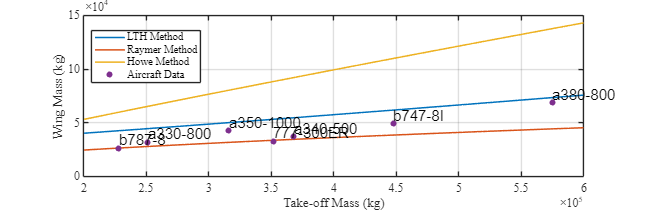



polarName = "xf-sc20712-il-1000000.csv";
shapeName = "sc20712.dat.txt";
airfoil = Airfoil();
airfoil = airfoil.readPolar(string(fullfile(polarPath, polarName)));
airfoil = airfoil.readShape(string(fullfile(XYPath, shapeName)));
airfoil = airfoil.interpShape(9);
Wtolist = linspace(200,600,100)*1e3*9.81;
for i = 1:length(Wtolist)
    Wto = Wtolist(i);
    Wpay = 8.7176e3*9.81;
    nult = 3.75;
    cruiserange = convlength(7500, 'naut mi',"m")*1e-3;
    cruise1 = cruise1.init(wing0.cbar);
    Wf = Wto * 0.4573;
    mLTH(i) = wingWeightLTH(wing0,airfoil.t_c,Wto)/9.81;
    mRaymer(i) = wingWeightRaymer(wing0,airfoil,Wto,nult,wing0.SREF*0.06)/9.81;
    mHowe(i) = wingWeightHowe(wing0, Wpay, Wto, nult, airfoil.t_c, 0.85*cruise1.a, cruiserange)/9.81;
    mShevell(i) = wingWeightShevell(wing0, airfoil,nult, Wto, Wf)/9.81;
end

% Define the aircraft names
aircraft_names = {'a330-800', 'a350-1000', 'b747-8I', 'a380-800', 'b787-8', '777-300ER', 'a340-500'};

% Aircraft data
mTO = [251000, 316000, 447696, 575000, 227930, 351534, 368000]; % Take-off mass (kg)
mwing = [31809, 42444, 49295, 68608, 26414, 32892, 36851];       % Wing mass (kg)

% Existing plots (assuming Wtolist, mLTH, mRaymer, mHowe are defined)
figure(5)
clf;
plot(Wtolist./9.81, mLTH)
hold on
plot(Wtolist./9.81, mRaymer)
hold on
plot(Wtolist./9.81, mHowe)
hold on
%plot(Wtolist./9.81, mShevell)
hold on

% Plot the scatter points
scatter(mTO, mwing, 'filled')

% Label each scatter point
for i = 1:length(mTO)
    text(mTO(i), mwing(i), aircraft_names{i}, 'VerticalAlignment','bottom', 'HorizontalAlignment','left', 'FontSize',15);
end

% Additional plot settings (optional)
xlabel('Take-off Mass (kg)')
ylabel('Wing Mass (kg)')
legend({'LTH Method', 'Raymer Method', 'Howe Method', 'Aircraft Data'}, 'Location', 'best')

grid on;                             % set the grid of the graph
set(gcf, 'Position', [0 0 860 280]); % show plot with larger size 